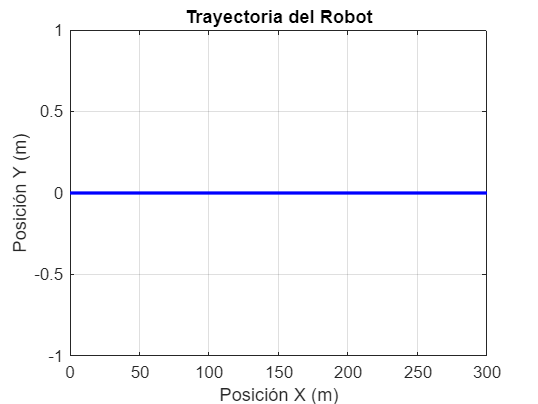

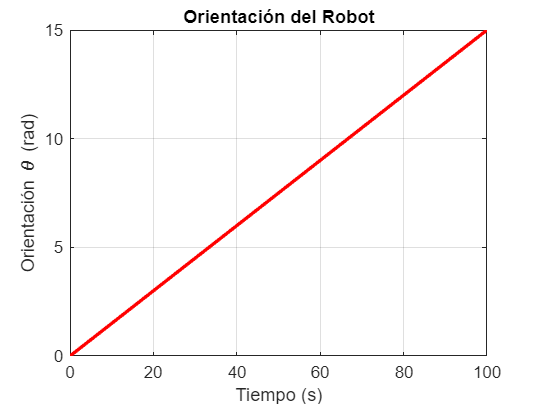

% Parámetros iniciales

x = 0;          % Posición inicial en x
y = 0;          % Posición inicial en y
theta = 0;      % Orientación inicial (rad)
v = 1;          % Velocidad lineal (m/s)
dt = 0.1;       % Paso de tiempo (s)
t_max = 500;     % Tiempo total de simulación (s)
w = 0;        % Velocidad angular (rad/s)

% Inicialización de matrices de resultados
time = 0:dt:t_max;
x_traj = zeros(size(time));
y_traj = zeros(size(time));
theta_traj = zeros(size(time));

% Simulación
for i = 1:length(time)
    % Almacenar datos actuales
    x_traj(i) = x;
    y_traj(i) = y;
    theta_traj(i) = theta;
    
    % Actualización según las ecuaciones
    x = x + v * cos(theta) * dt;
    y = y + v * sin(theta) * dt;
    theta = theta + w * dt;
end

% Gráfica de resultados
figure;
plot(x_traj, y_traj, 'b-', 'LineWidth', 2);
xlabel('Posición X (m)');
ylabel('Posición Y (m)');
title('Trayectoria del Robot');
grid on;

% Gráfica de orientación
figure;
plot(time, theta_traj, 'r-', 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Orientación \theta (rad)');
title('Orientación del Robot');
grid on;
